# Through this example you will learn how to use MathWorks tools for various steps of the reinforcement learning workflow

## Reinforcement Learning Workflow

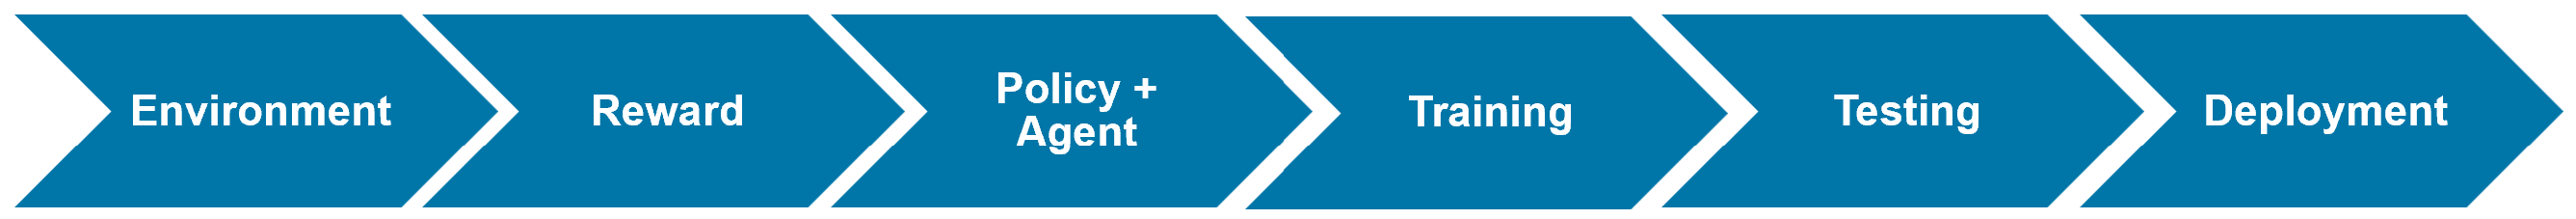

**Plant/Environment:** You will be using a discrete cart-pole system as your environment.

**Goal: **Train an RL agent to balance a discrete cart-pole system.

## Cart-Pole MATLAB Environment

The reinforcement learning environment for this example is a pole attached to an unactuated joint on a cart, which moves along a frictionless track. The training goal is to make the pole stand upright without falling over.

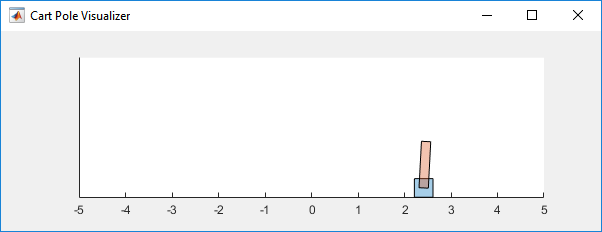

For this environment:

- The upward balanced pole position is 0 radians, and the downward hanging position is `pi` radians.

- The pole starts upright with an initial angle between –0.05 and 0.05 radians.

- The force action signal from the agent to the environment is discrete and either –10 or 10 N.

- The observations from the environment are the position and velocity of the cart, the pole angle, and the pole angle derivative.

- The episode terminates if the pole is more than 12 degrees from vertical or if the cart moves more than 2.4 m from the original position.

- Given the above goal you will be designing an appropriate reward signal.

## Create Environment Interface and Define Reward

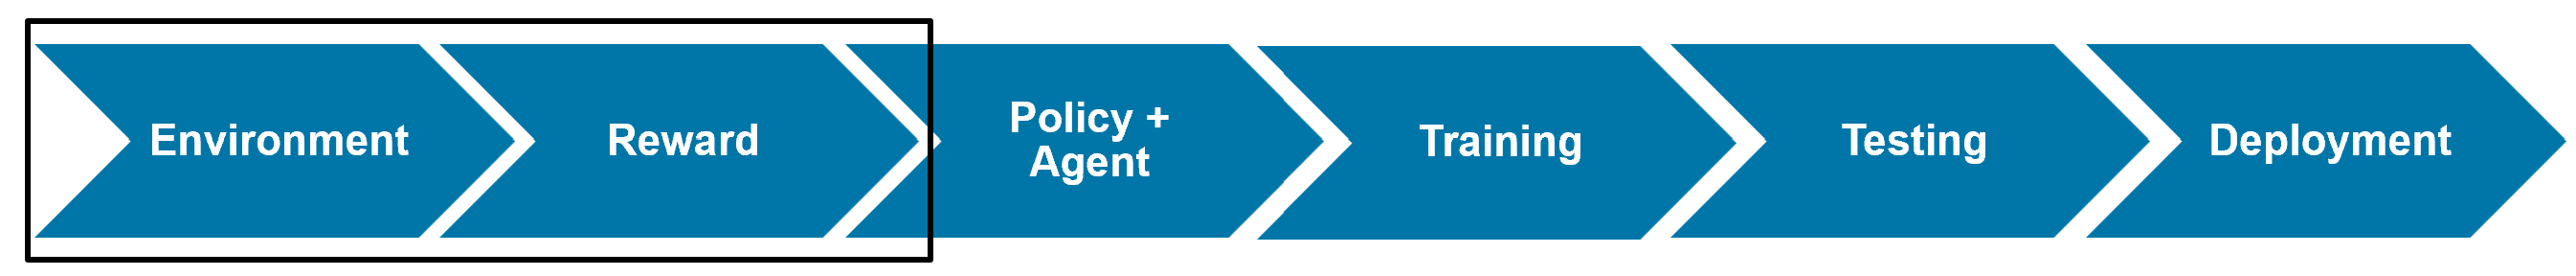

Creating an environment interface typically involves four parts:

- defining the observation and action spaces

- defining an optional reset function useful for domain randomization

- defining a step function

- defining a reward signal

#### Observation and Action Specifications

The observations from the environment are the cart position, cart velocity, pendulum angle, and pendulum angle derivative.

obsInfo = rlNumericSpec([4 1]);
obsInfo.Name = "CartPole States";
obsInfo.Description = 'x, dx, theta, dtheta';

The environment has a discrete action space where the agent can apply one of two possible force values to the cart: `-10` or `10` N.

actInfo = rlFiniteSetSpec([-10 10]);
actInfo.Name = "CartPole Action";

Why are we using [`rlNumericSpec`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.util.rlnumericspec.html) for the observations and [`rlFiniteSetSpec`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.util.rlfinitesetspec.html) for the actions?

It is because:

- The observations are discrete and the actions are discrete.

- The observations are continuous and the actions are discrete.

- The observations are discrete and the actions are continuous.

- The observations are continuous and the actions are continuous.

obs_act_info = 2;

Fix the random generator seed for reproducibility.

rng(0)

### Defining a reset function

For this example we have created a reset function for you. Please see the file "myResetFunction.m". The reset function is called at the beginning of every episode and the idea is to initialize the system with a random state so that the policy that the agent learns is robust. In this case the pole starts upright with an initial angle between –0.05 and 0.05 radians.

### Defining a step function

For this example we have created a step function for you. Please see the file "myStepFunction.m". Given the current observation and an action the step function is used to obtain the next observation, reward, and the isdone condition. The dynamics of the system are defined in the step function.

### Defining a reward signal

You will be creating your own reward signal in the "myStepFunction". Please use the goal mentioned above to help you define a reward signal. Note that the episode terminates if the pole is more than 12 degrees from vertical or if the cart moves more than 2.4 m from the original position. This is accomplished using the `IsDone` condition. This information can also be used in defining the reward signal. Type your reward code on line 69 onwards.

### Creating the environment object

Now that you have all the pieces needed for creating the environment you will be constructing the environment object using the "rlFunctionEnv" command. Here is an example of the command to use: 

`    env = rlFunctionEnv(observationInfo,actionInfo,"stepFunction","resetFunction");`

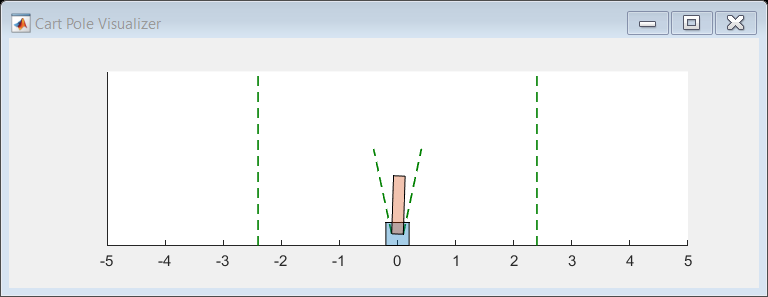

env = rlFunctionEnv(obsInfo,actInfo,"myStepFunction","myResetFunction");

Note that for this example we have already created a visualization of the environment which can be used to see how well the agent is performing.

## Create Policy + Agent

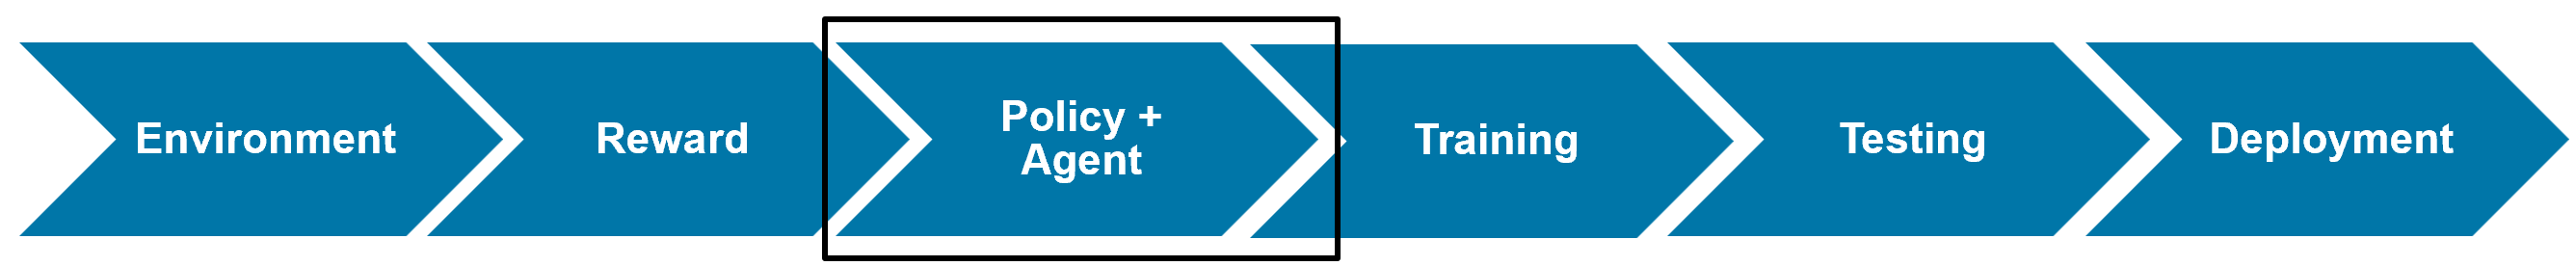

In the next step you will be creating the policy and agent. First you need to choose an RL agent/algorithm you will be using for this example. Please see this [link](https://www.mathworks.com/help/reinforcement-learning/ug/create-agents-for-reinforcement-learning.html#mw_13bb7b68-3087-4a9e-b55b-6bc920fa429e) for a list of built-in agents. You need to gather a list of compatible agents based on the observation and action space. For this example the observation space is continuous while the action space is discrete. Based on this information list the compatible built-in agent types below: 

DQN, PPO, TRPO, Q-Learning, and SARSA.

RL algorithms can be broadly classified into value-based, policy-based, and actor-critic. Depending on the type of algorithm used, you need to define policy (also known as actor) and value (also known as critic) functions.

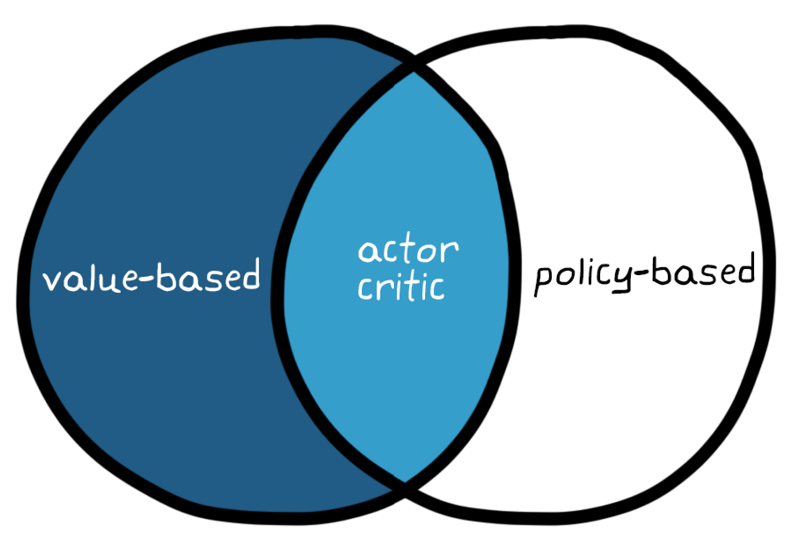

For this example we will be using the DQN agent which is a value-based method so it needs only value function (critic). Please see this [link](https://www.mathworks.com/help/reinforcement-learning/ug/dqn-agents.html) for details. DQN agents can use vector Q-value function critics. A vector Q-value function critic has observations as inputs and state-action values as outputs. Each output element represents the expected cumulative long-term reward for taking the corresponding discrete action from the state indicated by the observation inputs. For more information on creating value-functions, see [Create Policy and Value Function Representations](docid:rl_ug#mw_2c7e8669-1e91-4d42-afa6-674009a08004).

To approximate the Q-value function within the critic, use a neural network with one input channel (the 4-dimensional observed state vector) and one output channel with two elements (one for the 10 N action, another for the –10 N action). Define the network as an array of layer objects, and get the dimension of the observation space and the number of possible actions from the environment specification objects.

net = [
    featureInputLayer(obsInfo.Dimension(1))
    fullyConnectedLayer(20)
    reluLayer
    fullyConnectedLayer(length(actInfo.Elements))
    ];

Convert to `dlnetwork` and display the number of weights.

net = dlnetwork(net);
summary(net)

   Initialized: true

   Number of learnables: 142

   Inputs:
      1   'input'   4 features



View the network configuration.

analyzeNetwork(net);

How are the input and output dimensions of the neural network related to the observations and actions?

- Input dimension is related to actions and output dimension is related to the observations.

- Input dimension is related to observations and output dimension is related to the actions.

- There is no relation between any of them.

io_choice = 2;

Create the critic approximator using `net` and the environment specifications. For more information, see [`rlVectorQValueFunction`](docid:rl_ref#mw_7a9361cb-5a3b-4aba-a231-0966c5966233).

critic = rlVectorQValueFunction(net,obsInfo,actInfo);

Check the critic with a random observation input.

getValue(critic,{rand(obsInfo.Dimension)})

ans = 2×1 single column vector
    0.9745
   -0.0363


Create the DQN agent using `critic`. For more information, see [`rlDQNAgent`](docid:rl_ref#mw_167d0061-c095-446e-828f-816916a0f227).

agent = rlDQNAgent(critic);

Note that here we first define a critic and then use it to create an agent. We have a feature which creates default critic (along with appropriate neural networks) based on the observation and action specifications. If you are new to RL and neural networks, you can use this feature and it gives you a good starting point to iterate on. Please see this [link](https://www.mathworks.com/help/reinforcement-learning/ref/rl.agent.rldqnagent.html#mw_9095d51d-a58b-48c7-a575-cc9824a20b81) for detials regarding this feature. Sample code below:

`initOpts = rlAgentInitializationOptions(NumHiddenUnit=128);`

`agent = rlDQNAgent(obsInfo,actInfo,initOpts);`

`defaultCriticModel = getModel(getCritic(agent)); % getting the default critic model`

`analyzeNetwork(defaultCriticModel); % viewing the default critic neural network confirguration`

Check the agent with a random observation input.

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-10]}


Specify the DQN agent options, including training options for the critic. Alternatively, you can use [`rlDQNAgentOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagentoptions.html) and [`rlOptimizerOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.option.rloptimizeroptions.html) objects.

agent.AgentOptions.DiscountFactor = 0.99;
agent.AgentOptions.UseDoubleDQN = false;
agent.AgentOptions.TargetSmoothFactor = 1;
agent.AgentOptions.TargetUpdateFrequency = 4;
agent.AgentOptions.ExperienceBufferLength = 1e5;
agent.AgentOptions.MiniBatchSize = 256;
agent.AgentOptions.CriticOptimizerOptions.LearnRate = 1e-3;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold = 1;

#### Exploration vs Exploitation dilemma:

Exploration in the context of RL is to use a random action while exploitation is to use the best action given an observation using your current estimate of the Q-value function. It is important to balance these for the agent to learn well. In the case of DQN we use epsilon-greedy exploration. This means with a probability of $\epsilon$ we choose a random action otherwise we select the action for which the critic value function is greatest. Please see this [link](https://www.mathworks.com/help/reinforcement-learning/ref/rldqnagentoptions.html#mw_d66ae7b0-1964-4f66-a2ee-cfc08fc3657e_sep_mw_84f5fdc1-38e8-4861-88f5-e01921c30f0c) to understand how the various options used below affect the exploration. Try changing these options to see how it affects the learning outcomes.

agent.AgentOptions.EpsilonGreedyExploration.EpsilonDecay = 0.005;
agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 1;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonMin = 0.01;

## Train Agent

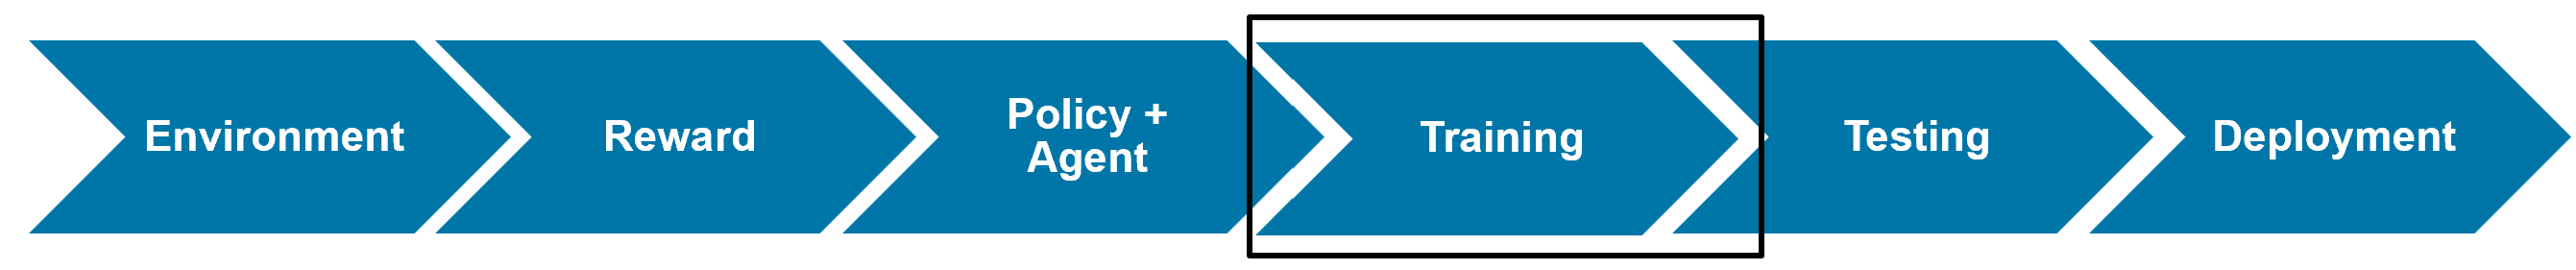

To train the agent, first specify the training options. For this example, we use the following options:

- Run one training session containing at most 1000 episodes, with each episode lasting at most 500 time steps.

- Display the training progress in the Episode Manager dialog box (set the `Plots` option) and disable the command line display (set the `Verbose` option to `false`).

- Stop training when the agent receives a moving average cumulative reward greater than 480. At this point, the agent can balance the cart-pole system in the upright position.

For more information, see [`rlTrainingOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.option.rltrainingoptions.html). Note that the `StopTrainingValue` and `SaveAgentValue` should be set based on the reward function you define. We chose a value of 480 based on our reward function. Change the `StopTrainingValue` and `SaveAgentValue` based on your reward function.

trainOpts = rlTrainingOptions(...
    MaxEpisodes=1000, ...
    MaxStepsPerEpisode=500, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=480,...
    SaveAgentCriteria="AverageReward",...
    SaveAgentValue=480); 

Train the agent using the [`train`](docid:rl_ref#mw_c0ccd38c-bbe6-4609-a87d-52ebe4767852) function. Training this agent is a computationally intensive process that takes several minutes to complete. To save time while running this example, you can load a pretrained agent by setting `doTraining` to `false`. To train the agent yourself, set `doTraining` to `true`.

doTraining = false;
if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("MATLABCartpoleDQNMulti.mat","agent");
end

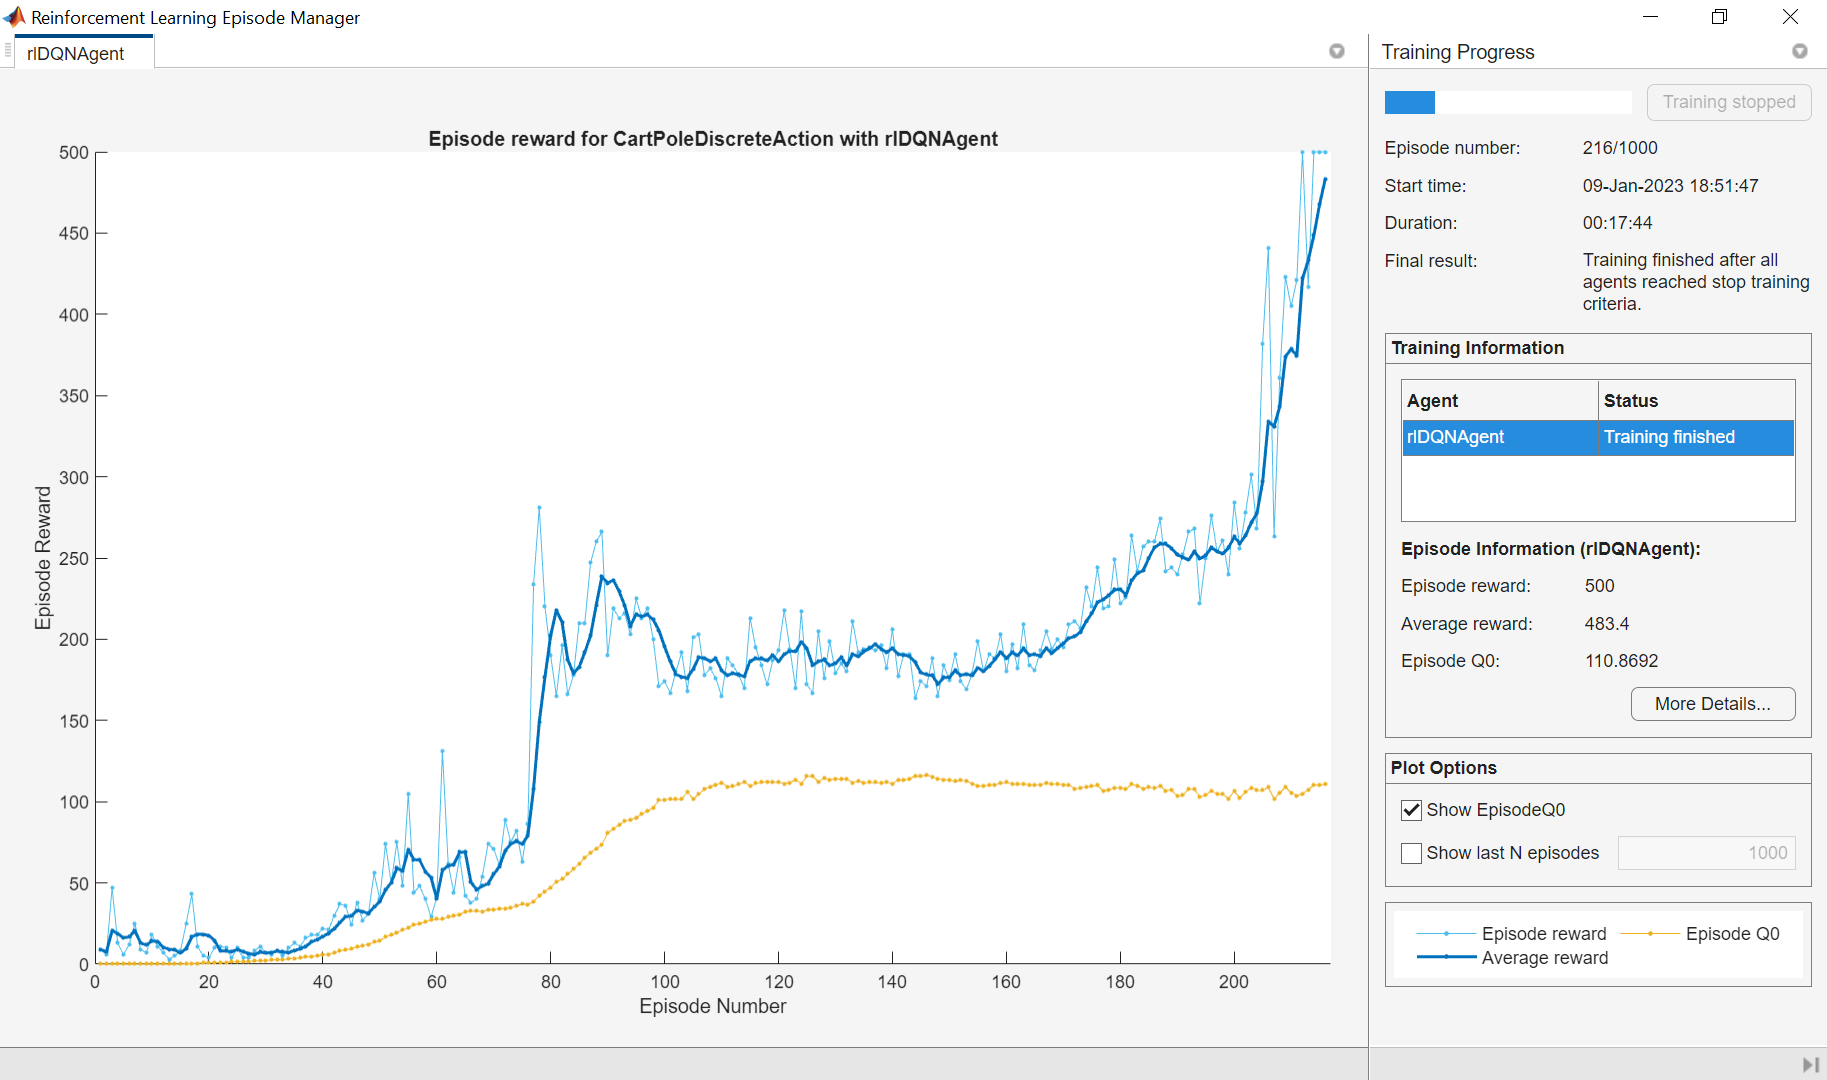

## Simulate/Testing DQN Agent

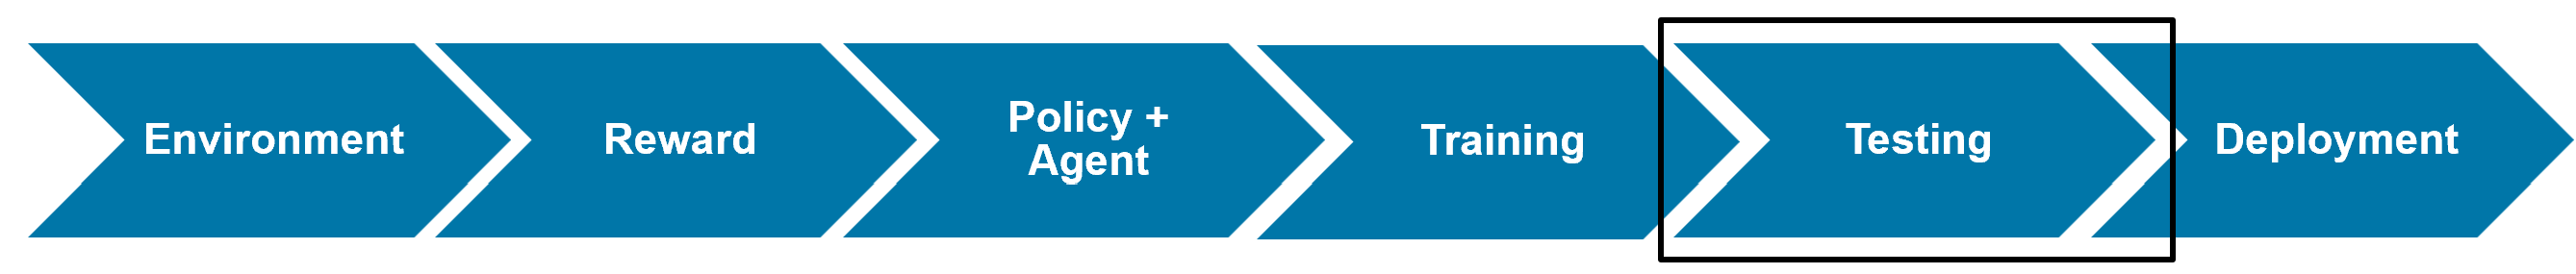

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.option.rlsimulationoptions.html) and [`sim`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.abstractenv.sim.html). You can use the visualization of the environment to see how well the trained agent is performing.

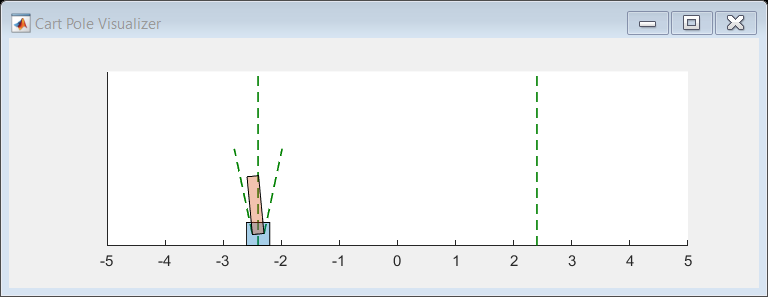

simOptions = rlSimulationOptions(MaxSteps=500,NumSimulations=5);
experience = sim(env,agent,simOptions);

totalReward = sum(experience(1).Reward)

totalReward = 469

## Deployment

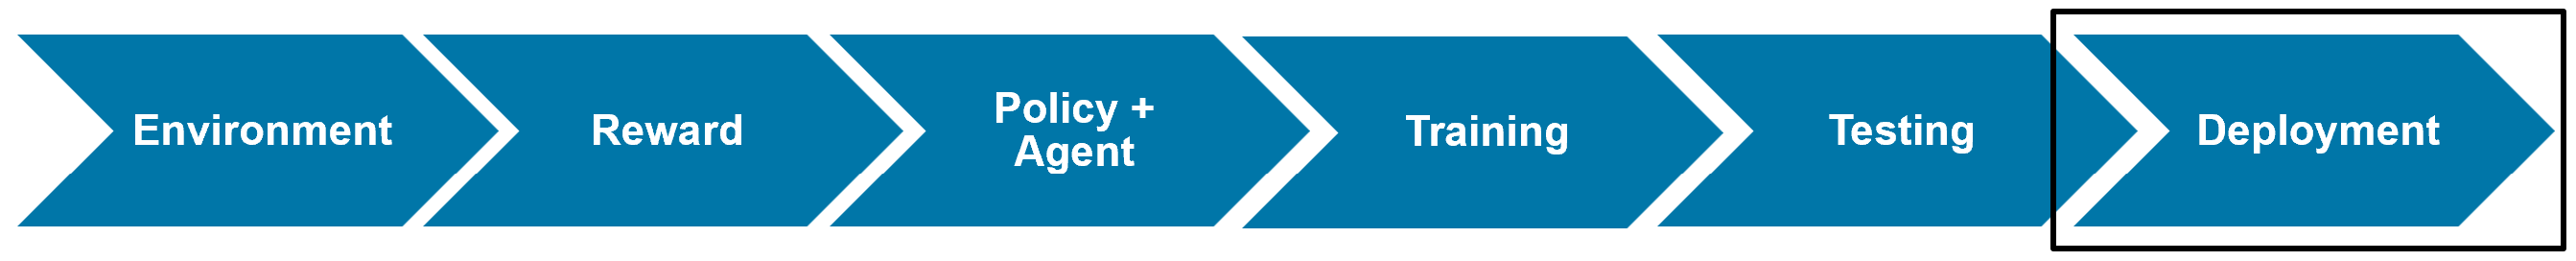

Once you are satisifed with the simulation results you can move on to the last step of the RL workflow which is to deploy the trained policy. Please see this [link](https://www.mathworks.com/help/reinforcement-learning/ug/deploy-trained-reinforcement-learning-agents.html) for details regarding deployment.

*Copyright 2019-2023 The MathWorks, Inc.*